clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',false,'Display','iter','FunctionTolerance',1e-4,'MaxFunctionEvaluations',150);

tic
[xv,Rv] = fmincon(@(x) objective(x),[0.5 0.9 1.6 0.4 10 8],[],[],[],[],[0 0 0 0 0 0],[3 3 3 3 100 100],[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    1.789192e+02    0.000e+00    1.848e+02
    1      14    1.274039e+02    0.000e+00    2.429e+02    2.559e+00
    2      21    4.683778e+00    0.000e+00    2.501e+02    4.376e-01
    3      41    4.377822e+00    0.000e+00    1.159e+01    2.935e-03
    4      49    4.377332e+00    0.000e+00    1.159e+01    4.905e-05
    5      59    4.417321e+00    0.000e+00    5.430e+02    3.132e-01
    6      68    3.452481e+00    0.000e+00    3.932e+02    9.212e-01
    7      77    2.133283e+00    0.000e+00    2.531e+02    7.916e-01
    8      84    5.316218e-01    0.000e+00    4.562e+01    9.817e-02
    9      94    3.167147e-01    0.000e+00    3.430e+01    1.749e-01
   10     102    2.844995e-02    0.000e+00    1.822e+01    5.761e-01
   11     109    5.977185e-03    0.000e+00    1.635e+00    9.907e-02
   12     116    2.403163e-03    0.000e+00    2

xv =     2.7136    0.3705    1.4745    0.2909   10.6300    8.5175


Rv = 3.1170e-04

toc

Elapsed time is 5.820209 seconds.


xv

xv =     2.7136    0.3705    1.4745    0.2909   10.6300    8.5175



A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3),A(4)), [A(5);A(6)], 0, 10, 0.01,  1e-9, A);
toc

Elapsed time is 3.174091 seconds.



L = sum((yf{end} - [10;10]).^2);

dL = full(getderivs(L))

dL =    -0.7843   16.0579    3.1919  -28.8970   -1.9284    0.2255


L = getvalue(L)

L = 0.1146


yfv=[];
dyfv=[];

for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end


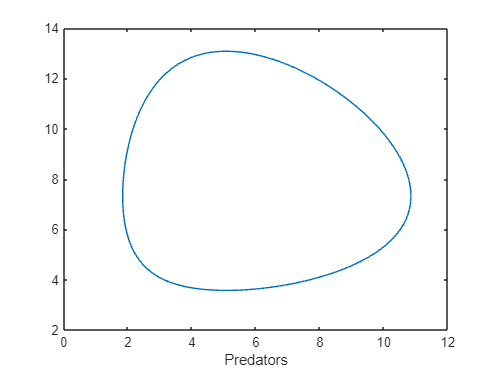

figure
plot(yfv(1,:),yfv(2,:))
xlabel('Prey')
xlabel('Predators')

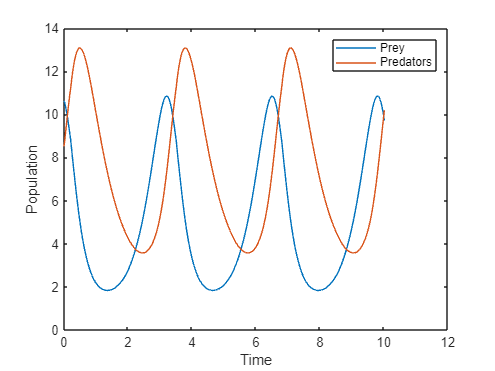


figure
plot(tf,yfv(1,:))
hold on
plot(tf,yfv(2,:))
xlabel('Time')
ylabel('Population')
legend('Prey','Predators')

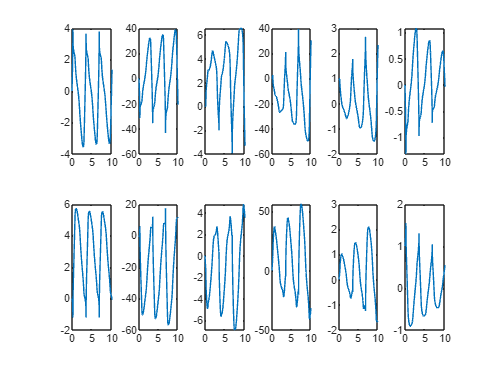


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L] = objective(x)

A = [x(1) x(2) x(3) x(4) x(5) x(6)];

[~, yf] = ODE.feuler(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3), A(4)), [A(5);A(6)], 0, 10, 0.001);

L = sum((yf{end} - [10;10]).^2);

end